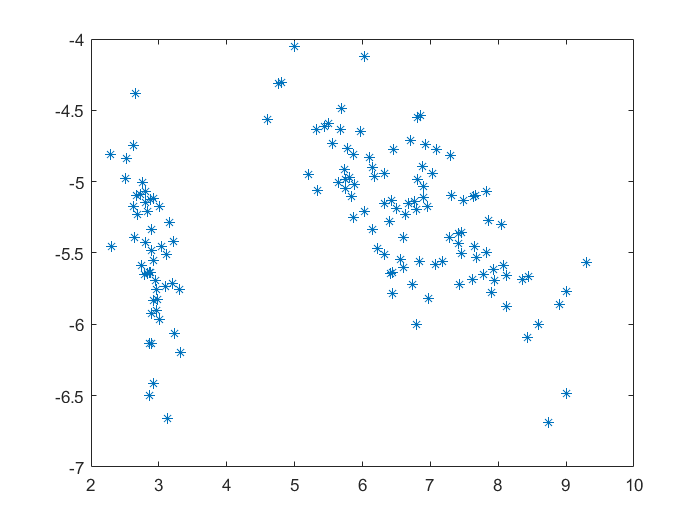

clear
clc

% load the data
Data = iris_dataset;
[row,col] = size(Data);

% 1. compute the mean;
m = mean(Data,2);

% 2. Compute the covariance matrix cov:  1/(col-1)

C = 1/col*(Data - m*ones(1,col))*(Data - m*ones(1,col))';

% 3. Eigendecomposition

[W,D] = eig(C);

% 4. Obtain the transformation matrix W_PCA
k = 2;
d = diag(D);
[~,inx] = sort(d,'descend');
W_PCA = W(:,inx(1:2));

% 5. Dimensionality reduction by PCA

Y = W_PCA'*Data;

% illustrate the 2-dimensional features
figure;
plot(Y(1,:),Y(2,:),'*');

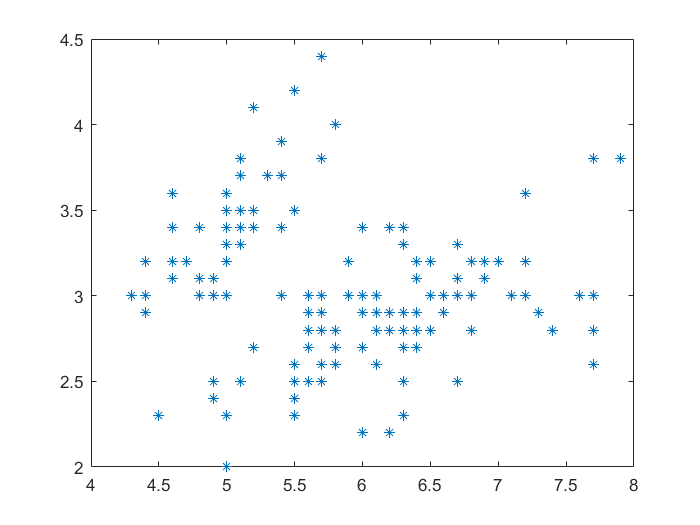

figure;
plot(Data(1,:),Data(2,:),'*');